# Conformal mapping 

A conformal mapping function is an analytical function that preserves the local angle (but not necessarily lengths) and whose derivative is non zero everywhere. 

We create a small grid and a circle in the $\zeta$- plane and transform it using different conformal mapping funtion into the $z$-plane. 

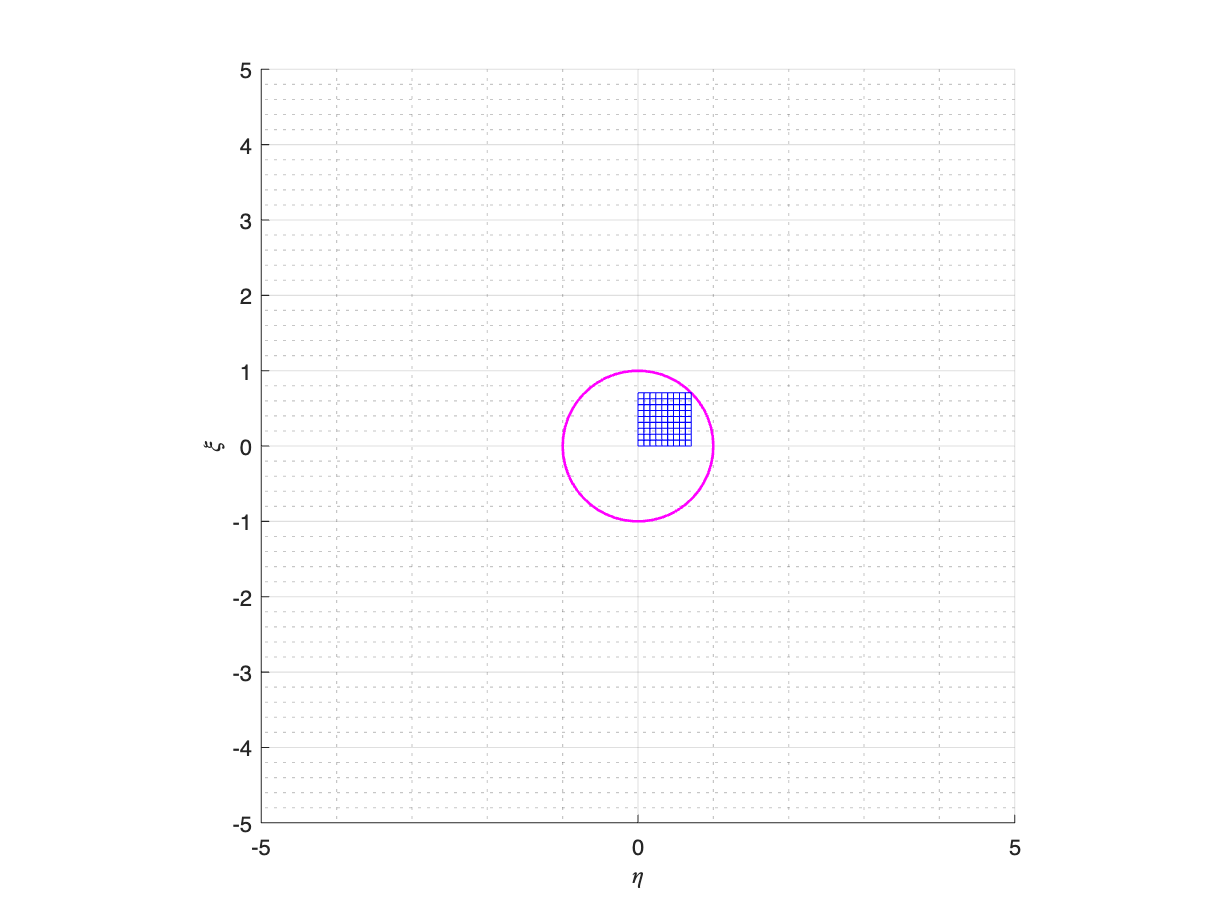

% a small grid in the first quadrant of the \zeta-plane
[ETAgrid,XIgrid]=meshgrid(linspace(0,sqrt(0.5),10));
ZETAgrid = ETAgrid+1i*XIgrid;
% a circle around the origin in the \zeta-plane
ZETAcircle = exp(1i*linspace(0,2*pi,51));
gridlevel = ones(10,10); % to help plot the grid

figure, hold all 
mesh(ETAgrid, XIgrid, gridlevel,'FaceColor','none','EdgeColor','blue')
plot(ZETAcircle,'m')
view(2), axis equal tight, axis([-5,5,-5,5]) 
grid on, grid minor
xlabel('\eta'), ylabel('\xi')

Let's look at a few examples of conformal mappings:

- 
$$z=f_1 \left(\zeta \right)=a\zeta +b\;$$
 

This transformation describes a **translation** (equal to *b*) and a **contraction/expansion** with a constant factor (equal to *a*)

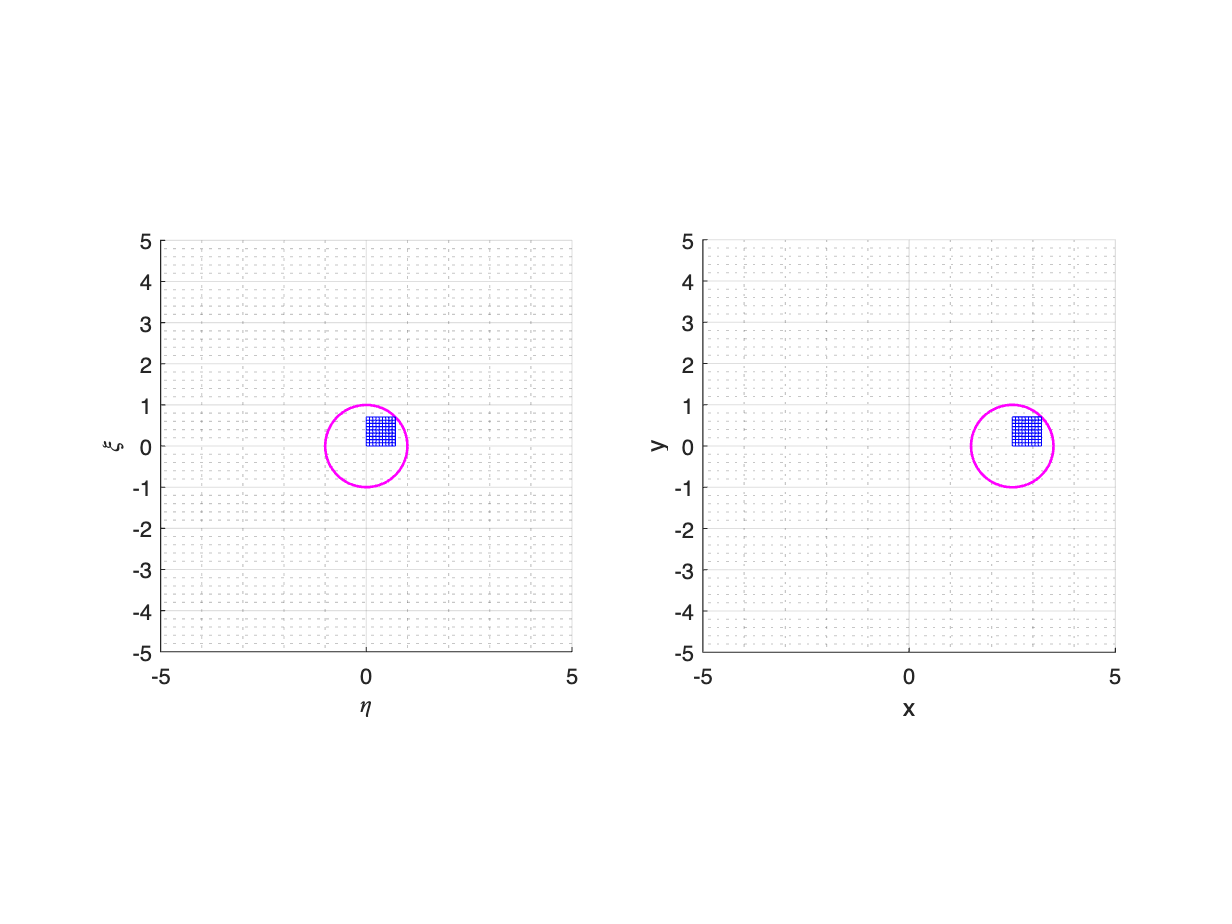

f1 = @(zeta,a,b) a*zeta+b; 

a = 1; 
b = 2.5; 

figure, 
subplot(1,2,1), hold all
mesh(ETAgrid, XIgrid, ones(10,10),'FaceColor','none','EdgeColor','blue')
plot(ZETAcircle,'m')
view(2), axis equal tight, axis([-5,5,-5,5]) 
grid on, grid minor
xlabel('\eta'), ylabel('\xi')
%
subplot(1,2,2), hold all
mesh(real(f1(ZETAgrid,a,b)),imag(f1(ZETAgrid,a,b)),gridlevel,'FaceColor','none','EdgeColor','blue')
plot(f1(ZETAcircle,a,b),'m')
view(2), axis equal tight, axis([-5,5,-5,5]) 
grid on, grid minor
xlabel('x'), ylabel('y')

- 
$$z=f_2 \left(\zeta \right)={\zeta e}^{i\alpha }$$


This transformation describes **pure rotation** about the origin over an angle $\alpha$

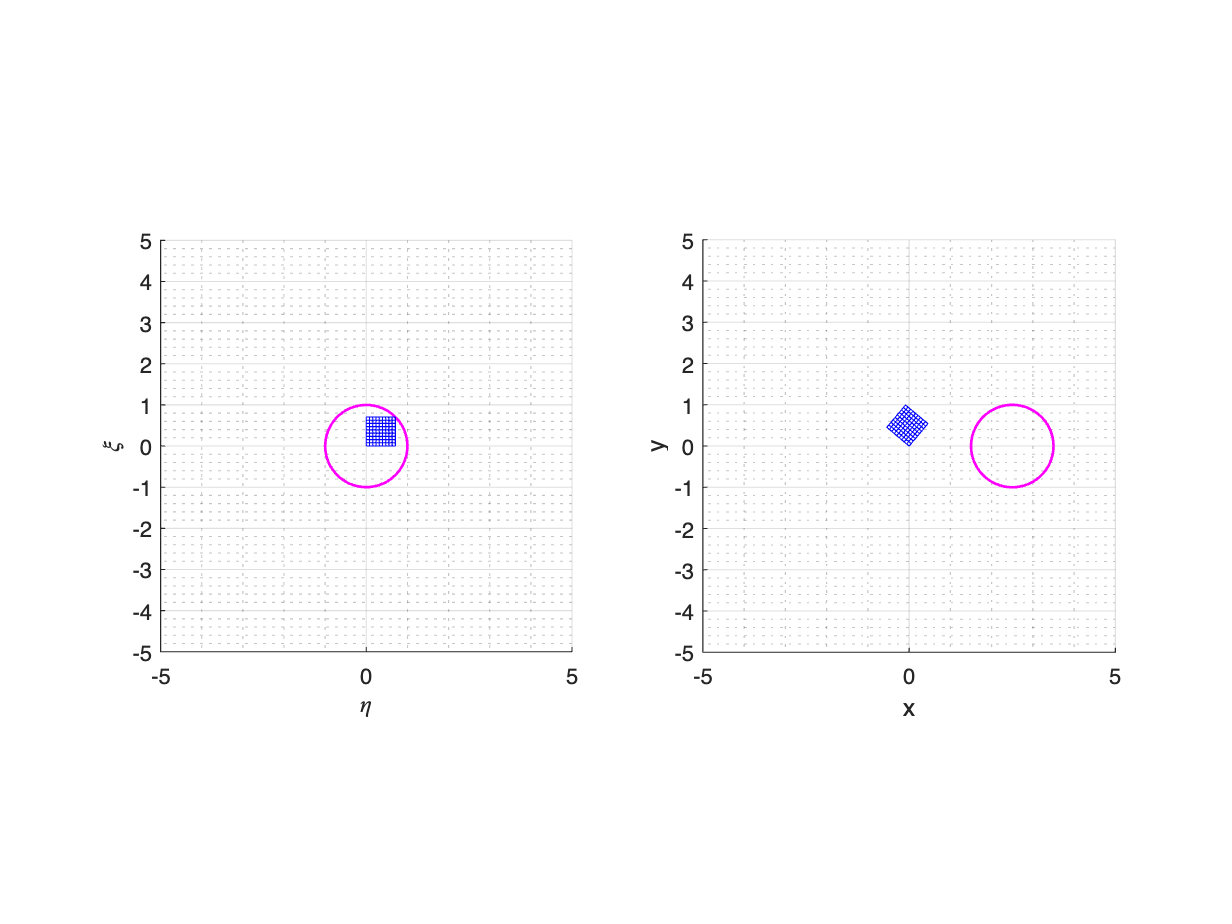

f2 = @(zeta,alpha) zeta*exp(1i*alpha); 

alpha = 50; % alpha in degree

figure, 
subplot(1,2,1), hold all
mesh(ETAgrid, XIgrid, ones(10,10),'FaceColor','none','EdgeColor','blue')
plot(ZETAcircle,'m')
view(2), axis equal tight, axis([-5,5,-5,5]) 
grid on, grid minor
xlabel('\eta'), ylabel('\xi')
%
subplot(1,2,2), hold all
mesh(real(f2(ZETAgrid,deg2rad(alpha))),imag(f2(ZETAgrid,deg2rad(alpha))),gridlevel,'FaceColor','none','EdgeColor','blue')
plot(f1(ZETAcircle,a,b),'m')
view(2), axis equal tight, axis([-5,5,-5,5]) 
grid on, grid minor
xlabel('x'), ylabel('y') 

- 
$$z=f_3 \left(\zeta \right)=\frac{c}{\zeta }$$


This transformation maps the interior area of a circle to the exterior

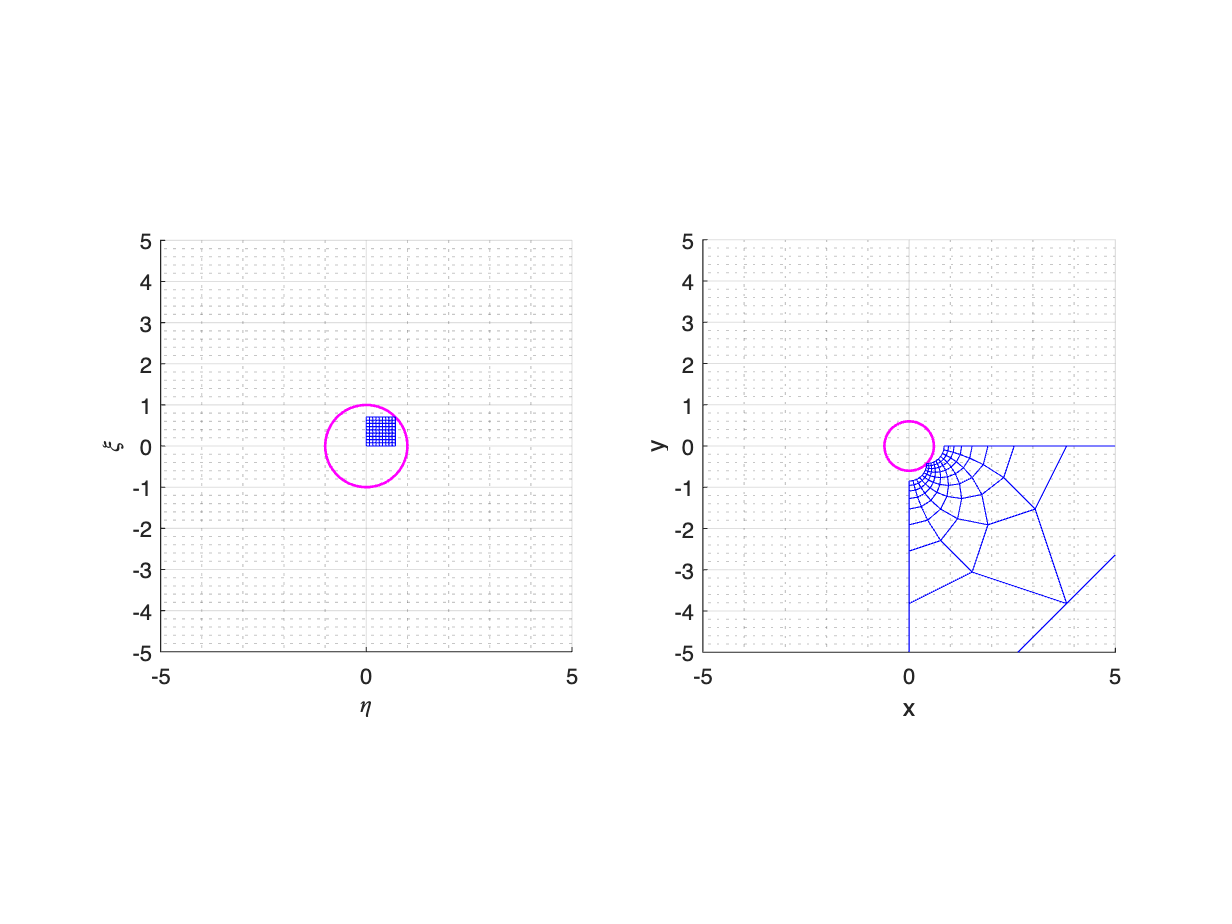

f3 = @(zeta,c) c./zeta; 

c = 0.6; 

figure, 
subplot(1,2,1), hold all
mesh(ETAgrid, XIgrid, ones(10,10),'FaceColor','none','EdgeColor','blue')
plot(ZETAcircle,'m')
view(2), axis equal tight, axis([-5,5,-5,5]) 
grid on, grid minor
xlabel('\eta'), ylabel('\xi')
%
subplot(1,2,2), hold all
mesh(real(f3(ZETAgrid,c)),imag(f3(ZETAgrid,c)),gridlevel,'FaceColor','none','EdgeColor','blue')
plot(f3(ZETAcircle,c),'m')
view(2), axis equal tight, axis([-5,5,-5,5]) 
grid on, grid minor
xlabel('x'), ylabel('y') 

- 
$$z=f_4 \left(\zeta \right)=\zeta^n$$


This transformation maps a sector in the $\zeta$- plane to another sector in the $z$-plane

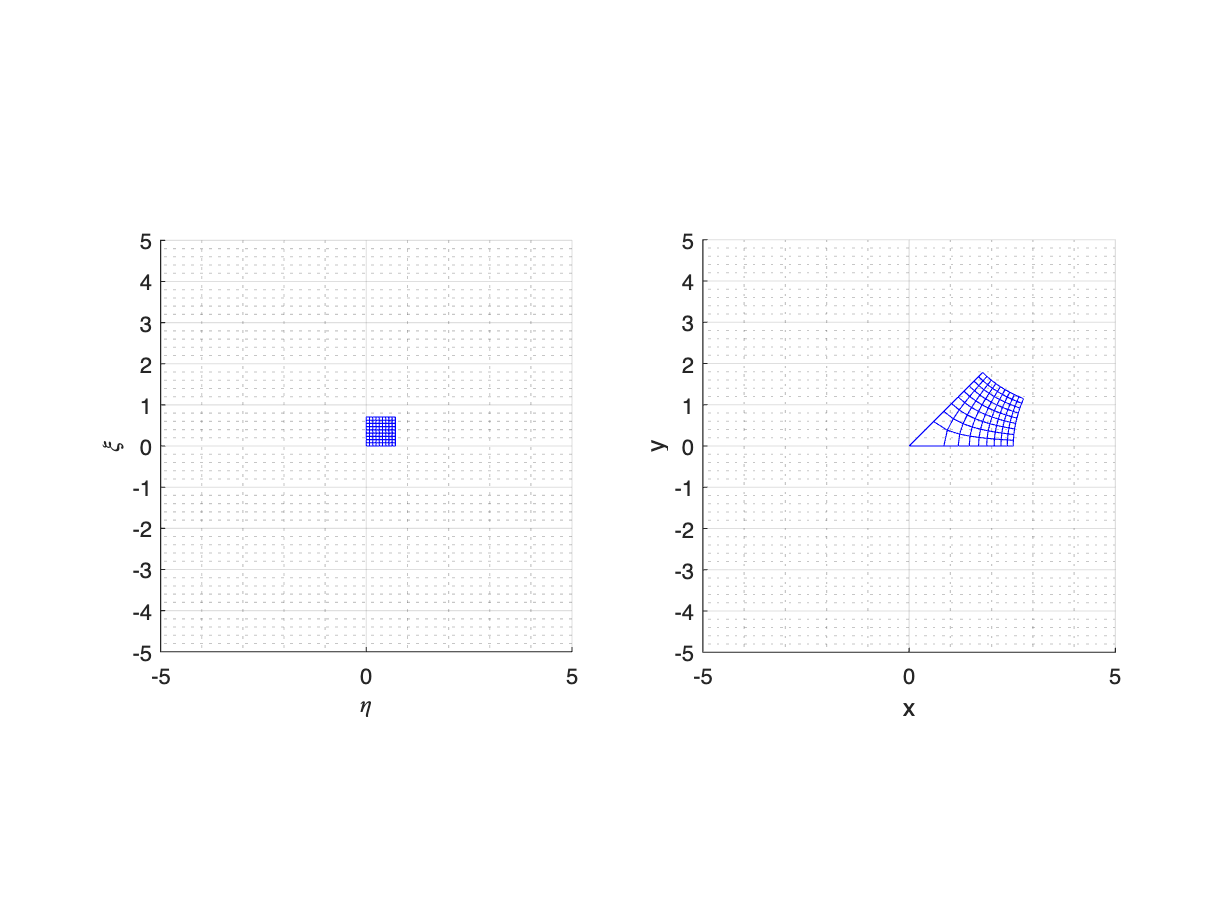

f4 = @(zeta,n) 3*zeta.^(n); 

n = 0.5; 

figure, 
subplot(1,2,1), hold all
mesh(ETAgrid, XIgrid, ones(10,10),'FaceColor','none','EdgeColor','blue')
view(2), axis equal tight, axis([-5,5,-5,5]) 
grid on, grid minor
xlabel('\eta'), ylabel('\xi')
%
subplot(1,2,2), hold all
mesh(real(f4(ZETAgrid,n)),imag(f4(ZETAgrid,n)),gridlevel,'FaceColor','none','EdgeColor','blue')
view(2), axis equal tight, axis([-5,5,-5,5]) 
grid on, grid minor
xlabel('x'), ylabel('y') 

-  
$$z=f_{\textrm{Joukowski}} \left(\zeta \right)=\zeta +\frac{a^2 }{\zeta }$$
 

This is the Joukowski transformation that we will use to transform circles into ellipses

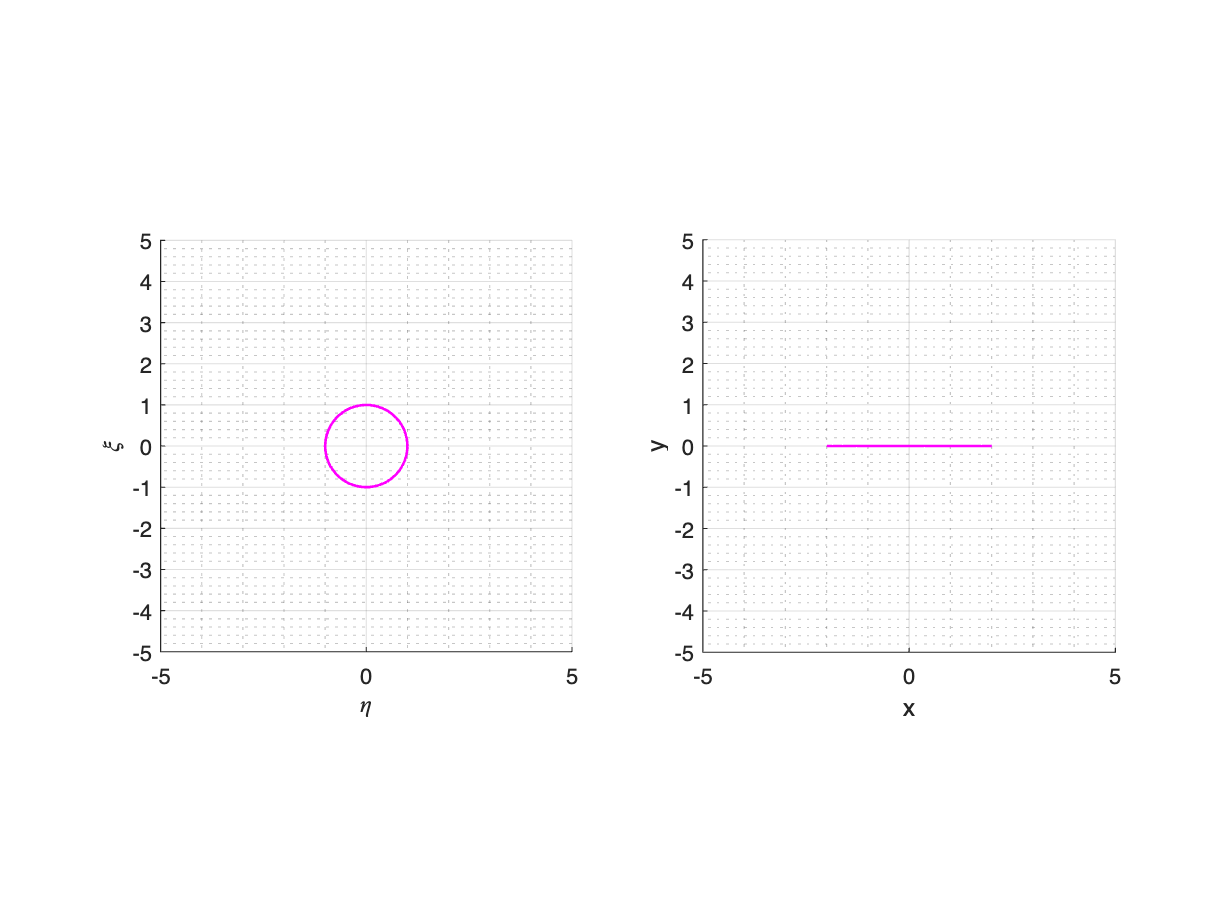

fJ = @(zeta,a) zeta + a^2./zeta; 

a = 1; 

figure, 
subplot(1,2,1), hold all
% mesh(ETAgrid, XIgrid, ones(10,10),'FaceColor','none','EdgeColor','blue')
plot(ZETAcircle,'m')
view(2), axis equal tight, axis([-5,5,-5,5]) 
grid on, grid minor
xlabel('\eta'), ylabel('\xi')
%
subplot(1,2,2), hold all
% mesh(real(fJ(ZETAgrid,a)),imag(fJ(ZETAgrid,a)),gridlevel,'FaceColor','none','EdgeColor','blue')
plot(fJ(ZETAcircle,a),'m')
view(2), axis equal tight, axis([-5,5,-5,5]) 
grid on, grid minor
xlabel('x'), ylabel('y') 